f = "E:\My_Dataset\Einstein\Einstein_1.JPG"

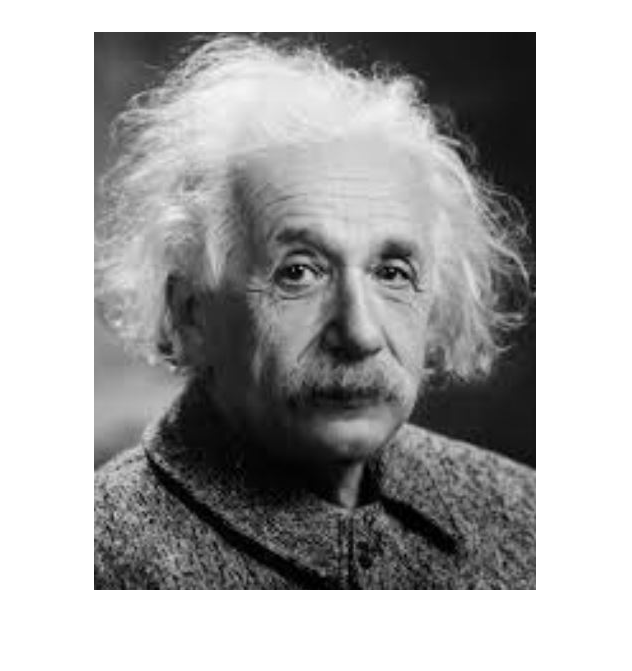

ans =     39     1


imds = imageDatastore("My_Dataset","IncludeSubfolders",true);
files = imds.Files;
parts = split(files, filesep);

for i=1:length(files)
    path = fullfile("E:",parts(i,end-2), parts(i,end-1), parts(i,end));
    image = readimage(imds,i);
    resized_image = imresize(image, [105 105]);
    size(resized_image);
    %gray_image = rgb2gray(resized_image);
    imwrite(resized_image,path);
end

imds = imageDatastore("FaceData_old","IncludeSubfolders",true);
files = imds.Files;
parts = split(files, filesep);

for i=1:length(files)
    extension = parts(i, end);
    filename = split(extension, ".");
    name = strcat(filename(1),".jpg");
    path = fullfile("E:",parts(i,end-2), parts(i,end-1), name);
    image = readimage(imds,i);
    resized_image = imresize(image, [105 105]);
    size(resized_image);
    %gray_image = rgb2gray(resized_image);
    imwrite(resized_image,path);
end